# Atividade 6 - Análise de sinais discretos

## João Victor Pessoa de Lima dos Anjos - 23.01078-9

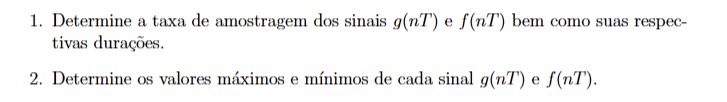

clear;
clear clc;

%%Para o sinal g(nT);
[x, fs] = audioread('Guitarra_limpa.wav');
g = x(:, 1);
N = length(g);
t = (0: N-1)/fs;
duracaoGuitarra = N/fs;
disp(['Taxa de amostragem da Guitarra: ', num2str(fs), ' Hz']);

Taxa de amostragem da Guitarra: 44100 Hz


disp(['Duração: ', num2str(duracaoGuitarra),' segundos']);

Duração: 13.4449 segundos


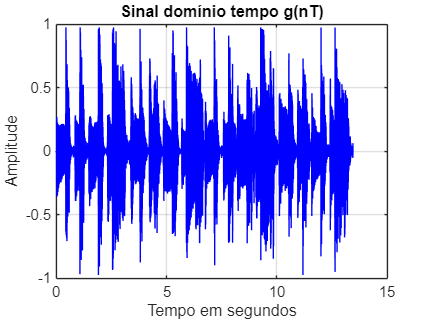


plot(t, g, 'b')
grid on
xlabel("Tempo em segundos")
ylabel("Amplitude")
title("Sinal domínio tempo g(nT)")


%%Valores máximos e mínimos para g(nT) EX2;
valorMaxGuitarra = max(g);
valorMinGuitarra = min(g);
disp(['Valor máximo g(nT): ', num2str(valorMaxGuitarra)]);

Valor máximo g(nT): 0.97504


disp(['Valor mínimo g(nT): ', num2str(valorMinGuitarra)]);

Valor mínimo g(nT): -0.97504



%%Energia de g(nT) EX3;
energiaGuitarra = sum(g.^2); 
disp(['Energia total de g(nT): ', num2str(energiaGuitarra)]);

Energia total de g(nT): 20041.83




%--------------------------------------------------------------------


%%Para o sinal f(nT);
[x, fs] = audioread('Gaita_blues.wav');
f = x(:, 1);
N_f = length(f);
t = (0: N_f-1)/fs;
duracaoGaita = N_f/fs;
disp(['Taxa de amostragem da Gaita: ', num2str(fs), ' Hz']);

Taxa de amostragem da Gaita: 44100 Hz


disp(['Duração: ', num2str(duracaoGaita),' segundos']);

Duração: 8.0035 segundos


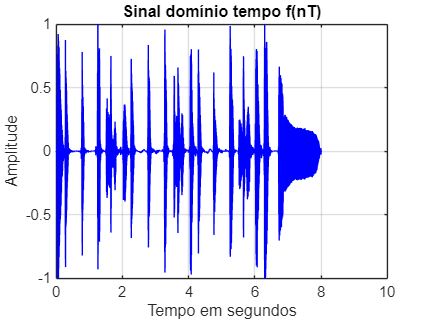


plot(t,f , 'b')
grid on
xlabel("Tempo em segundos")
ylabel("Amplitude")
title("Sinal domínio tempo f(nT)")


%%Valores máximos e mínimos para f(nT) EX2;
valorMaxGaita = max(f);
valorMinGaita = min(f);
disp(['Valor máximo f(nT): ', num2str(valorMaxGaita)]);

Valor máximo f(nT): 0.99997


disp(['Valor mínimo f(nT): ', num2str(valorMinGaita)]);

Valor mínimo f(nT): -1



%%Energia de f(nT) EX3;
energiaGaita = sum(f.^2); 
disp(['Energia total de f(nT): ', num2str(energiaGaita)]);

Energia total de f(nT): 7902.2114


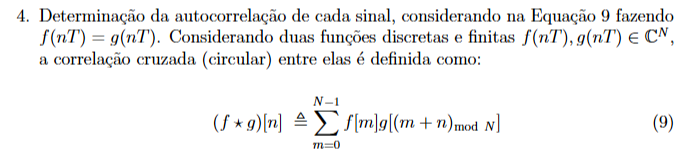

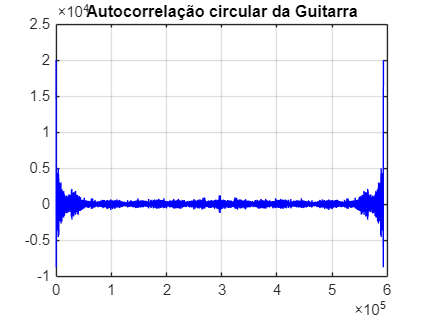

%%Autocorrelação circular
%%guitarra
r_guitarra = ifft(fft(g) .* conj(fft(g)));
lags_guitarra = 0:(length(g)-1);

figure;
plot(lags_guitarra, real(r_guitarra), 'b')
grid on
title('Autocorrelação circular da Guitarra (g(nt))')

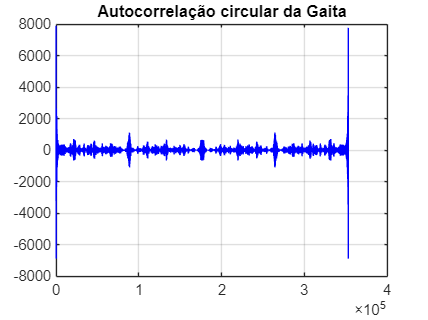


%%gaita
r_gaita = ifft(fft(f) .* conj(fft(f)));
lags_gaita = 0:(length(f)-1);

figure;
plot(lags_gaita, real(r_gaita), 'b')
grid on
title('Autocorrelação circular da Gaita (f(nt))')

%%Quando os sinais são semelhantes ou idênticos, a correlação será alta, 
%percebeu-se uma correspondência mais clara entre eles no domínio do tempo (e no som).
% Quando os sinais são diferentes, a correlação será mais baixa, e o som resultante será menos coerente.

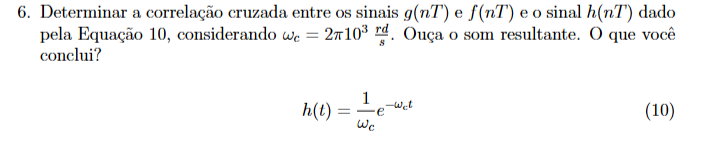

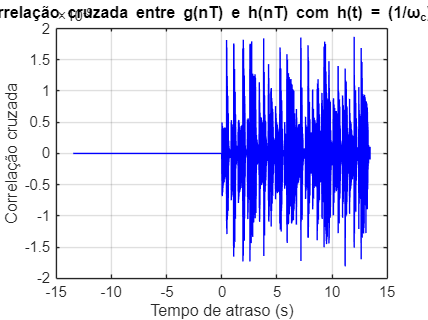

N_common = max(N, N_f);
g = [g; zeros(N_common - N, 1)];
f = [f; zeros(N_common - N_f, 1)];
t = (0:N_common-1)/fs;

%%h(nT) = (1/omega_c) * exp(-omega_c * t)
omega_c = 2 * pi * 1e3; 
h = (1/omega_c) * exp(-omega_c * t)';

%% Correlação cruzada entre g(nT) e h(nT)
R_gh = xcorr(g, h, 'biased');

%% Plot da correlação cruzada
tau = -N_common+1:N_common-1;
figure;
plot(tau/fs, R_gh, 'b');
xlabel('Tempo de atraso (s)');
ylabel('Correlação cruzada');
title('Correlação cruzada entre g(nT) e h(nT) com h(t) = (1/ω_c)e^{-ω_c t}');
grid on;


%% Ouvir o som resultante
disp('Som da correlação cruzada entre g(nT) e h(nT):');

Som da correlação cruzada entre g(nT) e h(nT):


soundsc(R_gh, fs);
